# 二阶系统响应分析

本脚本用于分析经典二阶系统（弹簧-质量-阻尼系统）的特性，为零极点配置提供一定参考。

考虑系统的传递函数为：$H(s)=\frac{\omega_n^2}{s^2+2\zeta\omega_ns+\omega_n^2}$

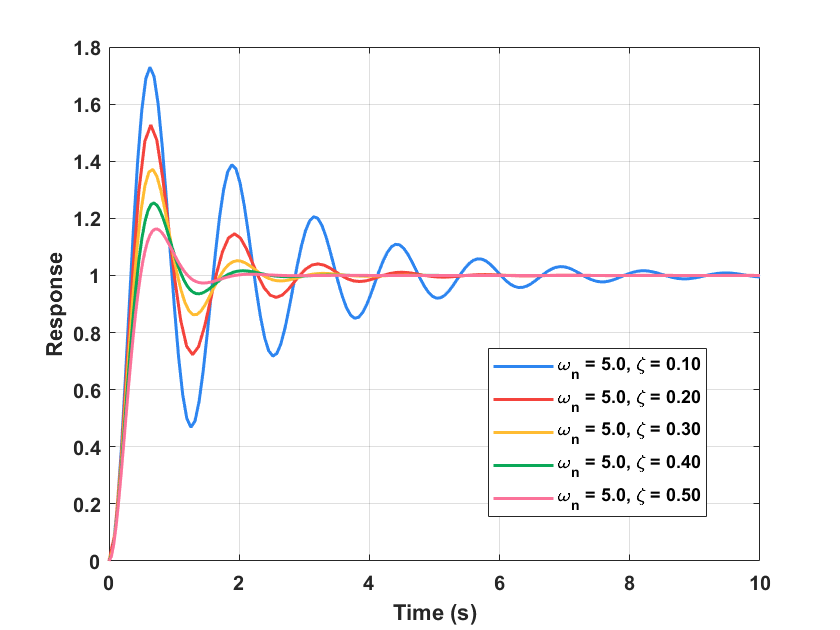

set(groot,'DefaultLineLineWidth',1.5)
set(groot,'DefaultAxesFontSize',10)
set(groot,'DefaultFigureColor','w')
set(groot,'DefaultAxesFontWeight','bold')

wn = 5;
zeta = 0.5;
T = 10;

info = sprintf('\\omega_n = %.1f, \\zeta = %.2f',wn,zeta);
s = tf('s');
Hs = wn^2/(s^2 + 2*zeta*wn*s + wn^2);

figure(1)
[y,t] = step(Hs,T);
plot(t,y,'DisplayName',info)
hold on
grid on
legend('Location','best')
xlim([0 T])
xlabel('Time (s)')
ylabel('Response')

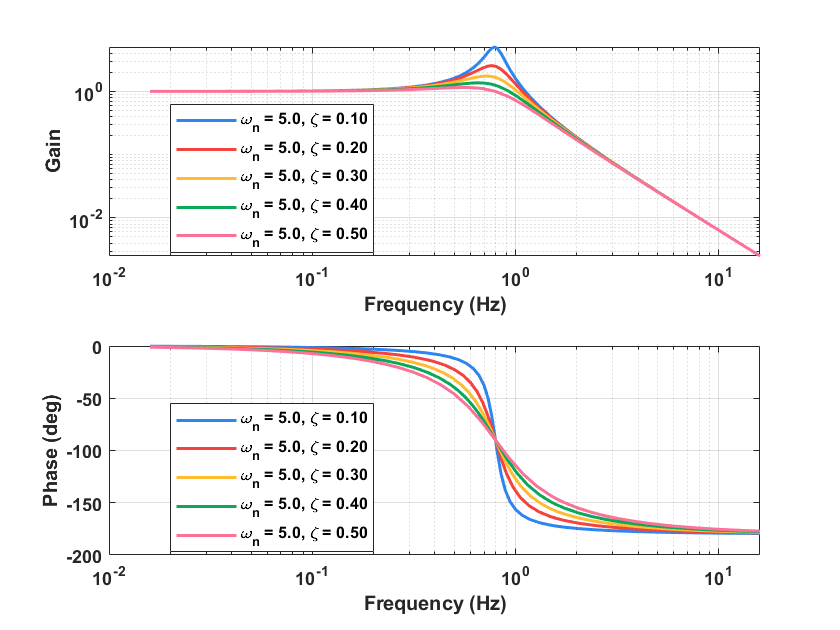


figure(2)
[mag,phase,w] = bode(Hs);
f = w/2/pi;
mag = squeeze(mag);
phase = squeeze(phase);
subplot(2,1,1)
loglog(f,mag,'DisplayName',info)
hold on
grid on
legend('Location','best')
xlabel('Frequency (Hz)')
ylabel('Gain')
subplot(2,1,2)
semilogx(f,phase,'DisplayName',info)
hold on
grid on
legend('Location','best')
xlabel('Frequency (Hz)')
ylabel('Phase (deg)')


[p,~] = pzmap(Hs);
fprintf('wn = %.1f, zeta = %.2f, poles: \n',wn,zeta)

wn = 5.0, zeta = 0.50, poles: 


disp(p)

  -2.5000 + 4.3301i
  -2.5000 - 4.3301i

